# Tipos de datos

**Ideas previas:**

Indistintamente de que se cree un escalar, un vector o una matriz, MATLAB creará arreglos bidimensionales para cada caso.

Además, por defecto MATLAB asignará el tipo de dato numérico `double` (doble) a las variables numéricas creadas. Sin embargo, a continuación se estudiará qué otros tipos de datos existen y cuál es su utilidad.

El tipo de datos (también llamado clase) principal en MATLAB es el arreglo o matriz. Dentro del arreglo, MATLAB soporta algunos tipos diferentes de datos secundarios.

En general, todos los datos dentro de un arreglo deben ser del mismo tipo. Sin embargo, MATLAB también incluye funciones para convertir entre tipos de datos y tipos de arreglos, para almacenar diferentes tipos de datos en el mismo arreglo (arreglos celda y estructura).

A continuación, se muestran los tipos de datos que se puede almacenar en MATLAB:

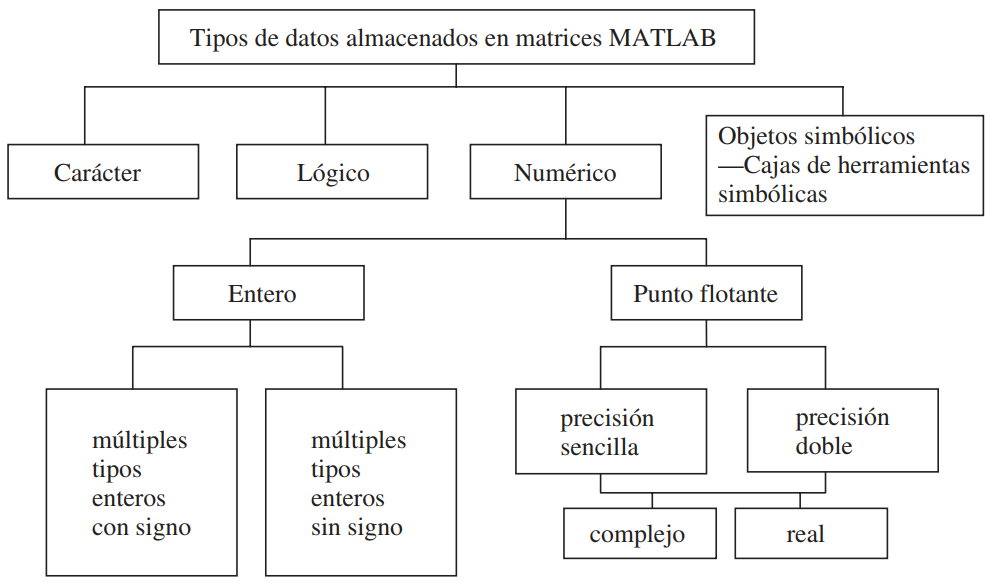

A su vez, también se muestran los tipos de arreglos que se pueden obtener con MATLAB:

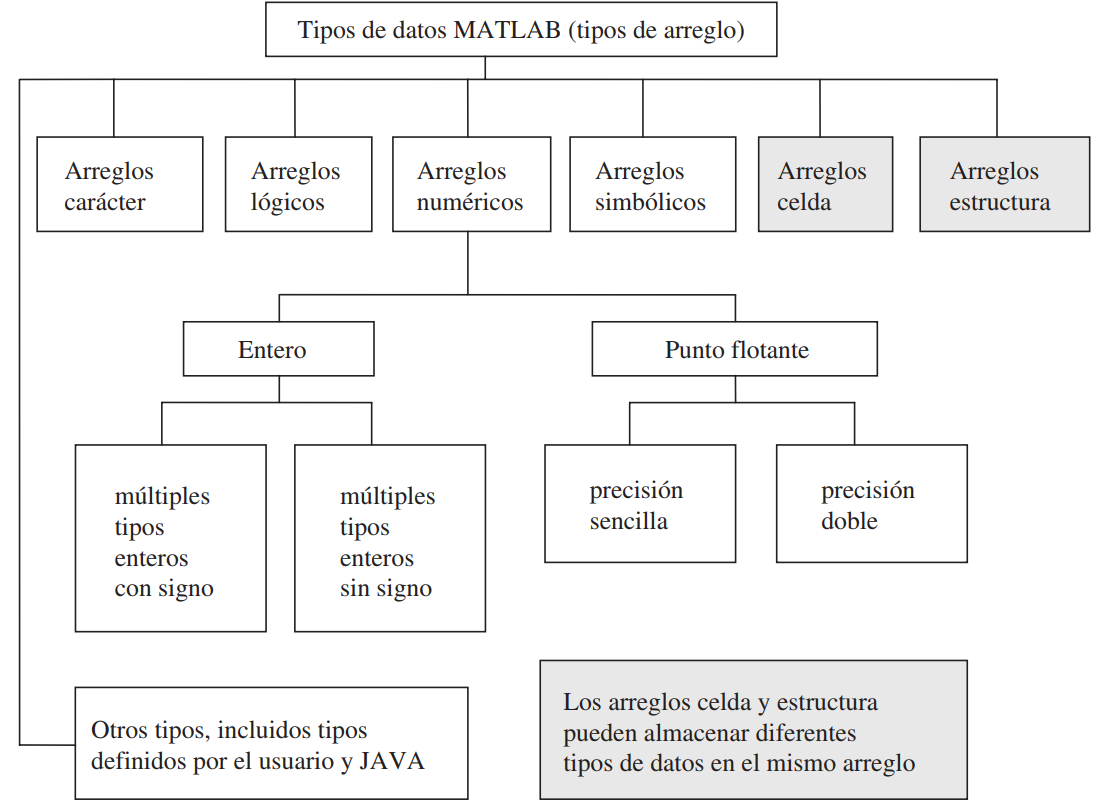

**Nota:** Un detalle importante es que sin importar el tipo de dato que se asigne a una variable, ésta siempre será un arreglo en MATLAB.

## Datos numéricos

### Números punto flotante de precisión doble

Tipo de dato numérico por defecto en MATLAB. Este tipo de números son los denominados `double` (aunque en otros lenguajes se los conoce como `float` de doble precisión) y sus características son las siguientes:

- Es el tipo dato numérico más grande del que se dispone en MATLAB.

- Muy recomendado para evitar problemas de redondeo.

- Cada `double` ocupa 8 bytes (64 bits) de almacenamiento. Por ejemplo, si un arreglo contiene 4 `double`, ese arreglo tendrá un tamaño de 32 bytes.

- Para conocer el `double` más grande que puede almacenar MATLAB se puede utilizar la función `realmax`. Cualquier número por encima de `realmax` MATLAB lo interpreatará como infinito (`Inf`).

- Para conocer el `double` más pequeño que puede almacenar MATLAB se puede utilizar la función `realmin`. Cualquier número por debajo de `realmin` MATLAB lo interpreatará como cero.

clear

g = 9.81;
whos

**Nota:** Un detalle importante es que, a excepción de este tipo de dato numérico, todos los tipos de datos numéricos se deben especificar. Es decir, si no se quiere utilizar un `double` y se quiere utilizar un `single`, por ejemplo, se debe especificar.

A continuación se detalla más.

### Números punto flotante de precisión sencilla

Se podría decir que este tipo de número (`single`) es el que viene detrás del `double`. Entre sus características se tiene:

- Utilizan la mitad del espacio de almacenamiento de un `double`.

- Se debe especificar que se quiere utilizar este tipo de dato mediante la función `single`.

- Como se puede intuir, al requerir menos espacio también almacena menos información.

- Para conocer el `single` máximo se utiliza la función `realmax('single')`.

- Para conocer el `single` mínimo se utiliza la función `realmin('single')`.

- Al igual que pasaba para los `double`, si se crea un número mayor que el `realmax('single')` MATLAB interpretará el valor como `Inf`. Para un número menor al `realmin('single')` la interpretación será cero.

a = single(g);
whos

### Números enteros

El concepto de número entero para MATLAB (`int`), o para la programación en general, es el mismo que todos dominamos: números sin parte decimal. Ahora bien, MATLAB dispone de 8 tipos de números enteros los cuales se detallan a continuación:

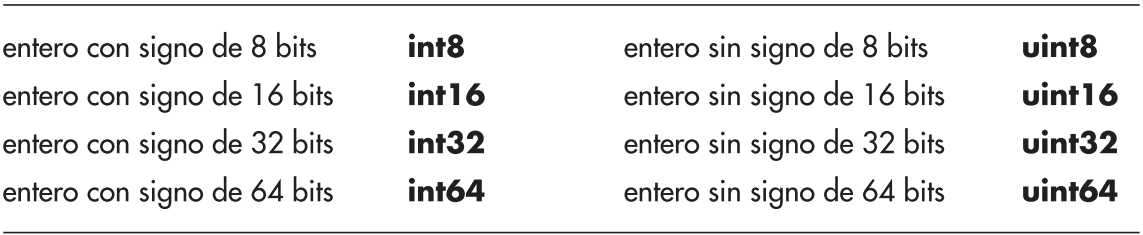

Los enteros del tipo `int` (integer) pueden ser positivos o negativos, y el espacio de almacenamiento determina cuál es su límite.

Los enteros del tipo `uint` (unsigned integer) no tienen signo, lo que técnicamente los hace positivos siempre.

Para consultar el límite de un entero (de cualquier tipo) se utiliza la función `intmax`. Por ejemplo, `intmax('int32')` devolvería el límite de los enteros de 32 bits con signo. La función `intmin` devuelve el mínimo.

Aquí puede volver la pregunta de ¿por qué tantos enteros? Pues bien, la respuesta es la misma que se dio para los `double` VS. `single`: depende del uso. Si queremos almacenar número de materias tomadas en un semestre (`numberSubjects`), ¿cuál sería la utilidad de asignar tanto espacio con un `double` (8 bytes) a una variable `numberSubjects` que a lo sumo tendrá un valor menor de 10?

Recordemos que `double` tiene el límite más grande para datos numéricos. En lugar de usar un `double`, que es el tipo de dato numérico más grande (y por ende requiere más espacio), ¿qué tal usar un tipo de dato `int8` que requiere 8 bits (1 byte)? 

Se insiste en que parece ridículo pensar en que 7 bytes, por ejemplo, harán la diferencia. Sin embargo, una universidad tiene miles de estudiantes, ¿ahí se notará la utilidad de optimizar los recursos? La respuesta es obvia.

Otro ejemplo: la edad de una persona en un país. Es poco probable que la edad de una persona supere los 127 años (límite máximo de `int8`), ¿entonces no sería razonable utilizar un tipo de dato numéricos `int8` para optimizar procesos en lugar de un `double` o `single`? Teniendo en cuenta que un país tiene millores de ciudadanos esto sería bastante útil.

Sin embargo, quizá alguien se cuestione y piense que, aunque es poco probable, podría ser que una persona supere los 127 años. En ese caso tendríamos un problema puesto que si intenta ingresar un número mayor a 127 en un `int8` le devolverá siempre el máximo.

clear
edad01 = 35;

  Name      Size            Bytes  Class     Attributes

  g         1x1                 8  double              



edad02 = uint8(35);
whos

Pero, ¿la edad de una persona es siempre positiva, verdad? Entonces sería una mejor idea utilizar `uint8` que ocupa el mismo espacio pero el límite es mayor que el de `int8` porque `uint8` no guarda espacio para el signo. Entonces tendríamos

age = uint8(128)

Así hemos optimizado el proceso sin requerir de más espacio.

**En conclusión**, siempre dependerá de la situación el tipo de dato numérico que se escoja, siempre y cuando se trabajen con miles o cientos de miles de datos. Sin embargo, si se trabajan con pocos datos no es necesario darle muchas vueltas al asunto.

Pero no está demás haber explicado todo lo anterior.

## Datos caracter y cadena

Un caracter básicamente es una letra, número o símbolo; y una cadena es un arreglo de caracteres.

- Cada caracter ocupa un espacio de almacenamiento de 2 bytes.

- Los caracteres o cadenas de caracteres (`char`) se ingresan entre apóstrofes.

- En cambio, una cadena (`string`) se ingresa entre comillas dobles.

clear

  Name      Size            Bytes  Class     Attributes

  a         1x1                 4  single              
  g         1x1                 8  double              




H = 'a'                             % Caracter.

K = 'MATLAB es muy útil.'           % Vector de caracteres.

S = "¿Vamos a la Foch?"             % Cadena.
S = ["Isacc" "Gabriela"]
S = ['Isacc' 'Gabriela']
v01 = [[1 2 3] [4 5 6]]

¿Cuál es la diferencia entre una cadena y un caracter (o una cadena de caracteres)? Pues bien, una cadena (`string`) ocupa mucho más espacio que un caracter (o una cadena de caracteres: `char`).

Pero la principal diferencia entre una cadena y un caracter (o cadena de caracteres) es que una cadena no es iterable, mientras que un caracter (o cadena de caracteres) si lo es.

clear

a = 'Hola';     % Cadena de caracteres.
b = "Hola";     % Cadena.

  Name        Size            Bytes  Class     Attributes

  edad01      1x1                 8  double              
  edad02      1x1                 1  uint8               




for i = a       % Un caracter (o cadena de caracteres) es iterable.

age = uint8
128

   disp(i) 
end

for i = b       % Una cadena no es iterable.
    disp(i)
end

H = 'a'

K = 'MATLAB es muy útil.'

S = "¿Vamos a la Foch?"

S = 1×2 string array
    "Isacc"    "Gabriela"


S = 'IsaccGabriela'

v01 =      1     2     3     4     5     6


H
o
l
a


Hola


**Nota:** Los números son caracteres únicamente si se los ingresa entre apóstrofes, caso contrario MATLAB los reconoce como datos numéricos.